clc; clear all; close all;
dr=[0;(0.24*pi)/(((2).^0.5));0]

dr =          0
    0.5331
         0


dv=[0.03;0.01;-0.02]

dv =     0.0300
    0.0100
   -0.0200


ns=(2^0.5)/4    

ns = 0.3536

t=(pi)/ns

t = 8.8858



psi=ns*t

psi = 3.1416



    Phirr=[(4-3*cos(psi)),0,0;
        6*(sin(psi-psi)),1,0;
        0,0,cos(psi)]

Phirr =      7     0     0
     0     1     0
     0     0    -1



    Phirv=[sin(psi)/ns,(2-2.*cos(psi))/ns,0;
        (2*(cos(psi)-2))/ns,(4*sin(psi))/ns-(3*(psi))/ns,0;
        0,0,sin(psi)/ns]

Phirv =    -0.0000   11.3137         0
  -16.9706  -26.6573         0
         0         0   -0.0000


    Dr =(Phirr*dr)+(Phirv*dv)

Dr =     0.1131
   -0.2425
    0.0000


    Drnet=Dr-dr

Drnet =     0.1131
   -0.7757
    0.0000


    
    Phivr=[3*ns*sin(psi),0,0;
        6*ns*(cos(psi)-1),0,0;
        0, 0, -(ns*sin(psi))]

Phivr =    -0.0000         0         0
   -4.2426         0         0
         0         0    0.0000



    Phivv=[cos(psi),2*sin(psi),0;
        -2*sin(psi),4*cos(psi)-3,0;
        0,0,cos(psi)]

Phivv =    -1.0000   -0.0000         0
    0.0000   -7.0000         0
         0         0   -1.0000


    
    Dv =(Phivr*dr)+(Phivv*dv)

Dv =    -0.0300
   -0.0700
    0.0200




%Phirv=[((1./ns).*(sin(psi))),(2./ns).*(1-cos(psi)),0;(2./ns).*(cos(psi)-1),((4./ns).*(sin(psi)))-((3./ns).*(psi)),0;0,0,(1./ns).*(sin(psi))]

Dr1(:,1)=Dr(1,:,:);
Dr2(:,1)=Dr(2,:,:);
Dr3(:,1)=Dr(3,:,:);
DRR=(Dr1.^2+Dr2.^2+Dr3.^2).^0.5

DRR = 0.2676


Dv1(:,1)=Dv(1,:,:);
Dv2(:,1)=Dv(2,:,:);
Dv3(:,1)=Dv(3,:,:);
DVV=(Dv1.^2+Dv2.^2+Dv3.^2).^0.5

DVV = 0.0787

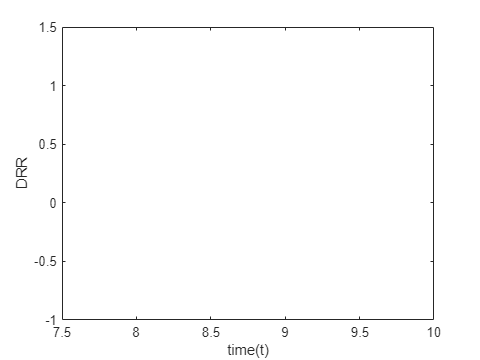



plot(t,DRR)
xlabel('time(t)')
ylabel('DRR')